%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 151433*0.946

W = 1.4326e+05


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.1

PerLamFlow = 0.1000


%Planform Parameters
S = 1619; %ft^2
AR = 8.6

AR = 8.6000

AR2 = 5.23

AR2 = 5.2300

b2=100

b2 = 100

TaperRatio = 0.6;
b = sqrt(AR*S)

b = 117.9975

Q = 1.01

Q = 1.0100

SweepQuartC = 0;
e = 0.9;

%Fuselage Parameters
Df = 15.08; %ft
LNose = 13.33; %ft
LMid = 54; %ft
LTail = 44.5 %ft

LTail = 44.5000

UpsweepAngle = 0.1757; %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = 300*2; %ft^2
ARv = 7.05;
TaperRatiov = 0.55;
bv = sqrt(ARv*Sv);
QVt = 1.05;
LocMaxTv = 0.35;
Tmaxv = 0.12

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = 400; %ft^2
ARh = 6.42;
TaperRatioh = 0.35;
bh = sqrt(ARh*Sh);
QHt = 1.05;
LocMaxTh = 0.35;
Tmaxh = 0.12

Tmaxh = 0.1200


[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 590.8000

M = 0.5817

Cr = 17.1508

Cmac = 14.0065

Ymac = 27.0411

SweepMaxT = -0.9992

Cf = 16.2740

Sexp = 1.3670e+03

Re = 4.6203e+07

SweepMaxT = -0.9992

FF = 1.5505

Swet = 2.8091e+03

CDo = 0.0062

[CDoWing2] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR2,b2,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 590.8000

M = 0.5817

Cr = 20.2375

Cmac = 16.5273

Ymac = 22.9167

SweepMaxT = -1.6428

Cf = 19.0168

Sexp = 1.3230e+03

Re = 5.4518e+07

SweepMaxT = -1.6428

FF = 1.5503

Swet = 2.7188e+03

CDo = 0.0059


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 590.8000

M = 0.5817

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Cf = 11.6939

Sexp = 400

Re = 2.8050e+07

SweepMaxT = -1.7183

FF = 1.4906

Swet = 815.7600

CDo = 0.0079


CDoHt = CDoHt*Sh/S

CDoHt = 0.0019


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 590.8000

M = 0.5817

Cr = 11.9036

Cmac = 9.4845

Ymac = 14.6861

SweepMaxT = -0.9437

Cf = 11.9036

Sexp = 600

Re = 3.1286e+07

SweepMaxT = -0.9437

FF = 1.4907

Swet = 1.2236e+03

CDo = 0.0077


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0014


[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

FF = 1.1657

CDoFuse = 0.0061


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0055


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag

CDoTotal = 0.0212

CDoTotal2 = CDoWing2 + CDoHt + CDoVt + CDoFuse + UpSweepDrag

CDoTotal2 = 0.0208


%Induced Drag Factor
% [TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
% AirDens = DensRat*2.3769*10^-3; %Slug/ft^3
% V=V*1.688
% M = V/SpeedSound
% 
% Ne = 0; %Num of engines ON TOP of Wing
% TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)
% K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)

K = 1/(e*pi*AR)

K = 0.0411

K2 = 1/(e*pi*AR2)

K2 = 0.0676


CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;
LDMax2 = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
   CD2(x) = CDoTotal2 + K2*CL(x)^2
   
   if CL(x)/CD2(x)>LDMax
       
       LDMax2 = CL(x)/CD2(x)
       
   end
   
end

CD = 0.0315

CD2 =     0.0377    0.0452    0.0445    0.0439    0.0433    0.0427    0.0420    0.0415    0.0409    0.0403    0.0398    0.0392    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310


CD2 =     0.0377    0.0371    0.0445    0.0439    0.0433    0.0427    0.0420    0.0415    0.0409    0.0403    0.0398    0.0392    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306


CD2 =     0.0377    0.0371    0.0364    0.0439    0.0433    0.0427    0.0420    0.0415    0.0409    0.0403    0.0398    0.0392    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0433    0.0427    0.0420    0.0415    0.0409    0.0403    0.0398    0.0392    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0427    0.0420    0.0415    0.0409    0.0403    0.0398    0.0392    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0420    0.0415    0.0409    0.0403    0.0398    0.0392    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0415    0.0409    0.0403    0.0398    0.0392    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0409    0.0403    0.0398    0.0392    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0403    0.0398    0.0392    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0398    0.0392    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0392    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0387    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0382    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0377    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0372    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0368    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0363    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0359    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0355    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0350    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0346    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0343    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0339    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0335    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD =     0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240


CD2 =     0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0332    0.0329    0.0325    0.0322    0.0319    0.0317    0.0314    0.0311    0.0309    0.0307    0.0305    0.0303    0.0301    0.0299    0.0298    0.0296    0.0295    0.0294    0.0293    0.0292    0.0291    0.0291    0.0290    0.0290    0.0290


CD = 1×26
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0329    0.0325    0.0322    0.0319


CD = 1×27
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0325    0.0322    0.0319


CD = 1×28
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0322    0.0319


CD = 1×29
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0319


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 0.4722

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


LDMax2 = 0.4801

CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 0.9438

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


LDMax2 = 0.9592

CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 1.4143

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


LDMax2 = 1.4364

CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 1.8832

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


LDMax2 = 1.9109

CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 2.3499

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


LDMax2 = 2.3817

CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 2.8139

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


LDMax2 = 2.8480

CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 3.2747

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


LDMax2 = 3.3088

CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 3.7317

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


LDMax2 = 3.7634

CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 4.1846

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


LDMax2 = 4.2111

CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 4.6327

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


LDMax2 = 4.6510

CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 5.0756

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


LDMax2 = 5.0826

CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 5.5130

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 5.9443

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 6.3692

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 6.7874

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 7.1983

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 7.6018

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 7.9975

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 8.3851

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 8.7644

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 9.1351

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 9.4971

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 9.8501

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 10.1939

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 10.5286

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 10.8538

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 11.1697

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 11.4760

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 11.7727

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 12.0599

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 12.3375

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 12.6055

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 12.8639

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 13.1129

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 13.3525

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 13.5826

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 13.8036

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 14.0154

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 14.2182

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 14.4120

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 14.5971

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 14.7736

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 14.9416

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 15.1014

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 15.2530

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 15.3966

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 15.5325

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 15.6608

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 15.7816

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 15.8953

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.0019

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.1016

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.1947

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.2814

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.3618

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.4360

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.5044

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.5671

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.6243

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.6761

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.7227

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.7644

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.8013

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.8335

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.8612

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.8847

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.9039

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.9192

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.9307

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.9385

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.9427

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


LDMax = 16.9436

CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


CD = 1×30
    0.0315    0.0310    0.0306    0.0303    0.0299    0.0295    0.0291    0.0288    0.0284    0.0281    0.0278    0.0274    0.0271    0.0268    0.0265    0.0262    0.0259    0.0257    0.0254    0.0251    0.0249    0.0246    0.0244    0.0242    0.0240    0.0237    0.0235    0.0234    0.0232    0.0230


CD2 = 1×30
    0.0377    0.0371    0.0364    0.0358    0.0351    0.0345    0.0339    0.0333    0.0328    0.0322    0.0316    0.0311    0.0306    0.0301    0.0296    0.0291    0.0286    0.0282    0.0277    0.0273    0.0269    0.0265    0.0261    0.0258    0.0254    0.0251    0.0247    0.0244    0.0241    0.0238


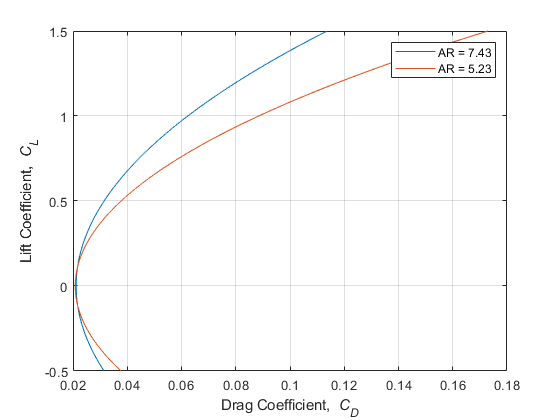


plot (CD,CL)
xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on
hold on
plot (CD2,CL)
hold off
legend('AR = 7.43','AR = 5.23')


LDMax

LDMax = 16.9436

LDMax2

LDMax2 = 5.0826